N = 1e4; 
SNR_dB = 0:5:20; 
pulse_width = 1; 
data = randi([0 1], N, 1); 
t = 0:0.01:pulse_width; pulse = ones(size(t)); 
tx_signal = reshape(repmat(data', length(t), 1) .* pulse', [], 1); 
BER = zeros(length(SNR_dB), 1); 
 
for k = 1:length(SNR_dB) 
               noise = sqrt(1 / (2 * 10^(SNR_dB(k)/10))) 
randn(size(tx_signal)); 
rx_signal = tx_signal + noise; 
filtered_signal = conv(rx_signal, pulse, 'same'); 
sampled_signal = filtered_signal(1:length(t):end); 
BER(k) = mean((sampled_signal > 0.5) ~= data); 
end 

noise = 0.7071

noise = 0.3976

noise = 0.2236

noise = 0.1257

noise = 0.0707

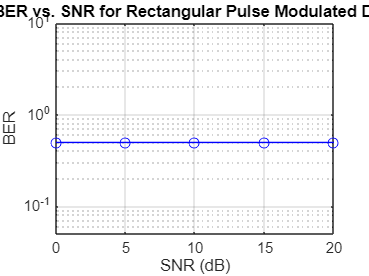

semilogy(SNR_dB, BER, 'b-o'); 
grid on; 
xlabel('SNR (dB)');  
ylabel('BER'); 
title('BER vs. SNR for Rectangular Pulse Modulated Data'); 